## High quality Users

According to the density histogram of the collected sensed data from traffic sensors & parking sensors (WiseIoT); good sensors producing data with the QoD is at about 0.92.

The historgram shows a beta distribution --> Using a beta distribution for modelling the quality of data that the users contribute.

# First shape parameter: a = 12;

# First shape parameter: b = 4.5;

x1 = linspace(0, 1, 1000);
y1 = betapdf(x1, 12, 4.5);
plot(x1,y1,'LineWidth',3)
title('Users Models: High Quality Users vs Low Quality Users vs Malicious Users');
xlabel('Quality of Data','FontSize',12);
ylabel('Probability Density','FontSize',12);
hold on;

## Low quality Users

According to the density histogram of the collected sensed data from traffic sensors & parking sensors (WiseIoT); good sensors producing data with the QoD is at about 0.78.

The historgram shows a beta distribution --> Using a beta distribution for modelling the quality of data that the users contribute.

# First shape parameter: a = 10;

# First shape parameter: b = 8;

x2 = linspace(0, 1, 1000);
y2 = betapdf(x2, 10, 8);
plot(x2,y2,'LineWidth',3)

## Malicious Users

We define malicious users as follows:

Sometimes the malicious users provides very good quality data as the fishing purpose; then most of the remaining time, it provide low quality data for malicious purposes.

Given alpha as the mixture coefficient between two models, 0 < alpha < 1,

Therefore, a bimodal distribution (of beta distribution) for modelling the QoD of this kind of users would be perfectly fit.

x3 = linspace(0, 1, 1000);
y3 = betapdf(x3, 5, 30); % low quality 
y4 = betapdf(x3, 20, 3); % high quality
alpha = 0.75;
% mixture coefficient
% the PDF for the bimodal distribution of the two beta distribution with the alpha mixture coefficient
% bimodal_betapdf = (1-alpha)*y3 + alpha*y4
plot(x3, (1-alpha)*y3 + alpha*y4,'LineWidth',3);

## Makeup the diagram

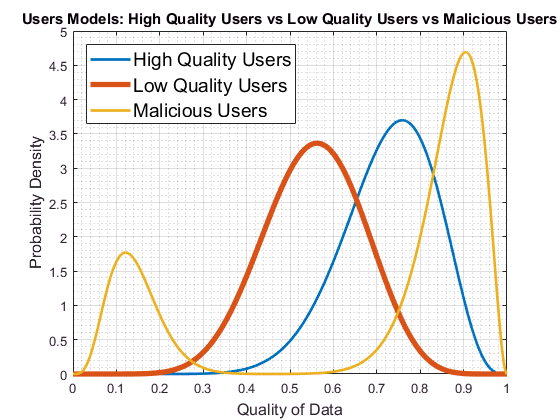

%yticklabels(linspace(0, 0.4, 9));
legend({'High Quality Users','Low Quality Users', 'Malicious Users'}, 'FontSize', 14, 'Location','northwest');
grid on;
grid minor;